## Fifth Test with Good Wheel Recording #1

clear;clc;clf
gauge = 14;
L = 248;
[y_true,Fs] = audioread("data/Trial 5/5-1.flac");

true_pluck = y_true;
t_true = linspace(0,length(true_pluck)/Fs,length(true_pluck));
% plot(t_true, true_pluck)
% title("One True Pluck Sound");
% ylabel("Amplitude");
% xlabel("Time (s)");
% sound(true_pluck, Fs)

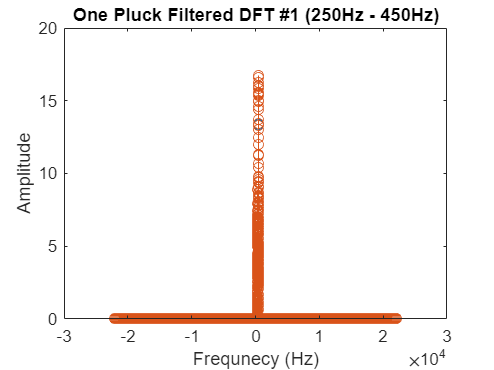

true_N = length(true_pluck);
true_f = linspace(-Fs/2, Fs/2 - Fs/true_N, true_N) + Fs/(2*true_N)*mod(true_N, 2);

true_pluckfft = fft(abs(true_pluck));

true_shiftpluckfft = fftshift(abs(true_pluckfft));
% 
% plot(true_f, true_shiftpluckfft)
% title("One True Pluck DFT");
% ylabel("Amplitude");
% xlabel("Frequnecy (Hz)")
% 
% 

filter = zeros(length(true_f), 1);
filter(true_f >= 250 & true_f <= 500) = 1;

filtered_true = true_shiftpluckfft .* filter;


stem(true_f, filtered_true)
title("One Pluck Filtered DFT #1 (250Hz - 450Hz)");
ylabel("Amplitude");
xlabel("Frequnecy (Hz)")


T = tension(L, true_f(filtered_true(:,1) == max(filtered_true(:,1))), gauge)

T = 969.4469

## Fifth Test with Good Wheel Recording #2

[y_true,Fs] = audioread("data/Trial 5/5-2.flac");

true_pluck = y_true;
t_true = linspace(0,length(true_pluck)/Fs,length(true_pluck));
% plot(t_true, true_pluck)
% title("One True Pluck Sound");
% ylabel("Amplitude");
% xlabel("Time (s)");
% sound(true_pluck, Fs)

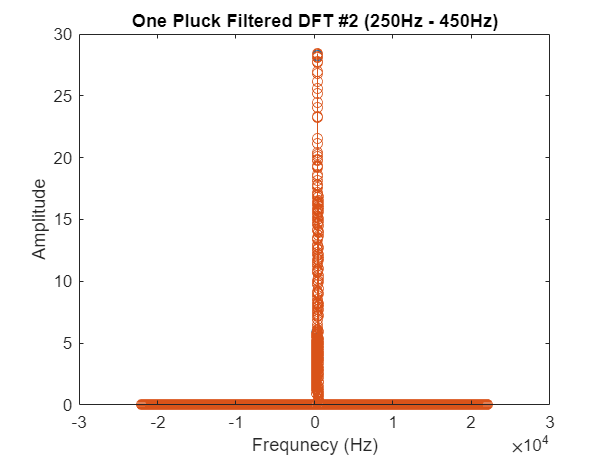

true_N = length(true_pluck);
true_f = linspace(-Fs/2, Fs/2 - Fs/true_N, true_N) + Fs/(2*true_N)*mod(true_N, 2);

true_pluckfft = fft(abs(true_pluck));

true_shiftpluckfft = fftshift(abs(true_pluckfft));
% 
% plot(true_f, true_shiftpluckfft)
% title("One True Pluck DFT");
% ylabel("Amplitude");
% xlabel("Frequnecy (Hz)")
% 
% 

filter = zeros(length(true_f), 1);
filter(true_f >= 250 & true_f <= 500) = 1;

filtered_true = true_shiftpluckfft .* filter;


stem(true_f, filtered_true)
title("One Pluck Filtered DFT #2 (250Hz - 450Hz)");
ylabel("Amplitude");
xlabel("Frequnecy (Hz)")


T = tension(L, true_f(filtered_true(:,1) == max(filtered_true(:,1))), gauge)

T = 1.0444e+03

## Fourth Test with Good Wheel Recording #3

[y_true,Fs] = audioread("data/Trial 5/5-3.flac");

true_pluck = y_true;
t_true = linspace(0,length(true_pluck)/Fs,length(true_pluck));
% plot(t_true, true_pluck)
% title("One True Pluck Sound");
% ylabel("Amplitude");
% xlabel("Time (s)");
% sound(true_pluck, Fs)

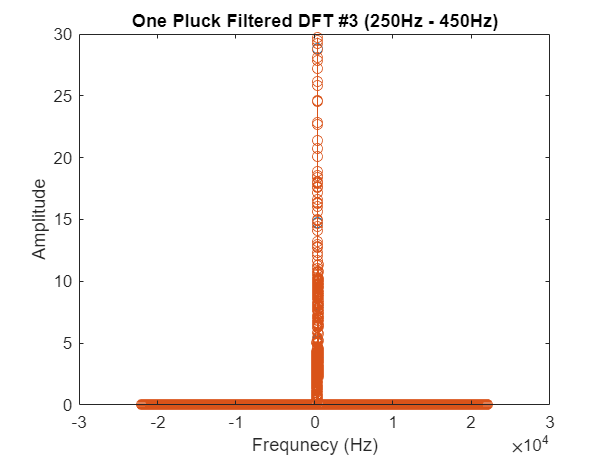

true_N = length(true_pluck);
true_f = linspace(-Fs/2, Fs/2 - Fs/true_N, true_N) + Fs/(2*true_N)*mod(true_N, 2);

true_pluckfft = fft(abs(true_pluck));

true_shiftpluckfft = fftshift(abs(true_pluckfft));
% 
% plot(true_f, true_shiftpluckfft)
% title("One True Pluck DFT");
% ylabel("Amplitude");
% xlabel("Frequnecy (Hz)")
% 
% 

filter = zeros(length(true_f), 1);
filter(true_f >= 250 & true_f <= 500) = 1;

filtered_true = true_shiftpluckfft .* filter;


stem(true_f, filtered_true)
title("One Pluck Filtered DFT #3 (250Hz - 450Hz)");
ylabel("Amplitude");
xlabel("Frequnecy (Hz)")


T = tension(L, true_f(filtered_true(:,1) == max(filtered_true(:,1))), gauge)

T = 1.0141e+03

## Fourth Test with Good Wheel Recording #1 Pullback

[y_true,Fs] = audioread("data/Trial 5/holdback-1.flac");

true_pluck = y_true;
t_true = linspace(0,length(true_pluck)/Fs,length(true_pluck));
% plot(t_true, true_pluck)
% title("One True Pluck Sound");
% ylabel("Amplitude");
% xlabel("Time (s)");
% sound(true_pluck, Fs)

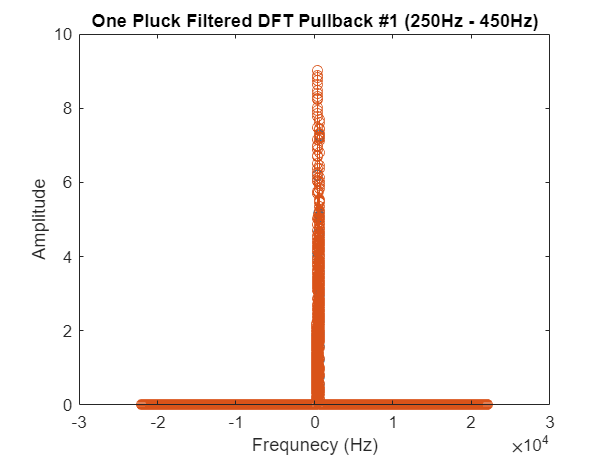

true_N = length(true_pluck);
true_f = linspace(-Fs/2, Fs/2 - Fs/true_N, true_N) + Fs/(2*true_N)*mod(true_N, 2);

true_pluckfft = fft(abs(true_pluck));

true_shiftpluckfft = fftshift(abs(true_pluckfft));
% 
% plot(true_f, true_shiftpluckfft)
% title("One True Pluck DFT");
% ylabel("Amplitude");
% xlabel("Frequnecy (Hz)")
% 
% 

filter = zeros(length(true_f), 1);
filter(true_f >= 250 & true_f <= 700) = 1;

filtered_true = true_shiftpluckfft .* filter;


stem(true_f, filtered_true)
title("One Pluck Filtered DFT Pullback #1 (250Hz - 450Hz)");
ylabel("Amplitude");
xlabel("Frequnecy (Hz)")


T = tension(L, true_f(filtered_true(:,1) == max(filtered_true(:,1))), gauge)

T = 1.1348e+03

## Fourth Test with Good Wheel Recording #2 Pullback

[y_true,Fs] = audioread("data/Trial 5/holdback-2.flac");

true_pluck = y_true;
t_true = linspace(0,length(true_pluck)/Fs,length(true_pluck));
% plot(t_true, true_pluck)
% title("One True Pluck Sound");
% ylabel("Amplitude");
% xlabel("Time (s)");
% sound(true_pluck, Fs)

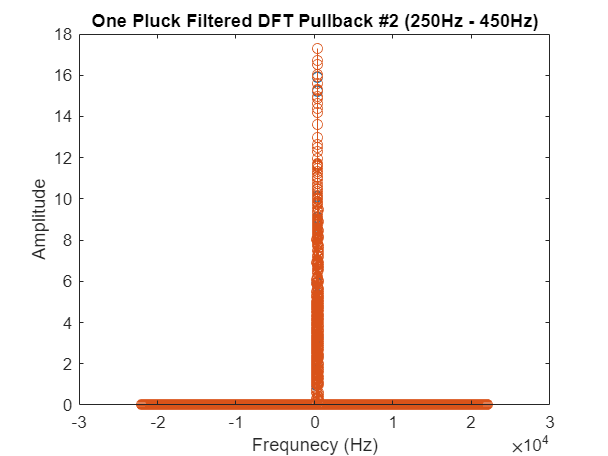

true_N = length(true_pluck);
true_f = linspace(-Fs/2, Fs/2 - Fs/true_N, true_N) + Fs/(2*true_N)*mod(true_N, 2);

true_pluckfft = fft(abs(true_pluck));

true_shiftpluckfft = fftshift(abs(true_pluckfft));
% 
% plot(true_f, true_shiftpluckfft)
% title("One True Pluck DFT");
% ylabel("Amplitude");
% xlabel("Frequnecy (Hz)")
% 
% 

filter = zeros(length(true_f), 1);
filter(true_f >= 250 & true_f <= 500) = 1;

filtered_true = true_shiftpluckfft .* filter;


stem(true_f, filtered_true)
title("One Pluck Filtered DFT Pullback #2 (250Hz - 450Hz)");
ylabel("Amplitude");
xlabel("Frequnecy (Hz)")


T = tension(L, true_f(filtered_true(:,1) == max(filtered_true(:,1))), gauge)

T = 999.0919